Load the clean data table that is the combination of line and in lab data collection:

D = readtable('inlab_online_combined.csv');

The table contains the etimated values from WMRL model fittings: 

- C: working memory capacity 

- phi_WM: working memory forgetting rate

- alpha: learning rate

- epsilon: error

- mix_w: initial mixing weight

- r0: initial reward value for a correct response

- pers: preservation 

- phi_RL: learning forgetting rate

- group: testing set

- nRealis: number of realis events in the recall

- nWords: number of words (length of) recall

- v17_total_events: total number of determined event boundaries

- v1NumEvent: number of determined event boundaries in movie v1

- v7NumEvent: number of determined event boundaries in movie v7

- allRecognitionAcc: accuracy (proportion correct) in recognition of temporal order of movie frames in both movies (averaged)

**Does the number of determined events in the movie correlate within subjects?** Does the person who determines many events in one movie does so in the other movie too? 

x = D.v1NumEvent;
y = D.v7NumEvent;
% the significance of the correlation 
[r,p] = corr(x,y,'type','spearman'); 
disp (['ranked correlation: r = ' num2str(r) ', p = ' num2str(p) ])

ranked correlation: r = 0.85967, p = 2.8675e-18


[r,p] = corr(x,y);
disp (['Pearson correlation: r = ' num2str(r) ', p = ' num2str(p) ])

Pearson correlation: r = 0.85229, p = 1.1129e-17


There is a significant correlation, so we infer that the grain of event segmentation is subjective. 

**Is there a link between the total number of determined events and working memory forgetting rate and working memory capacity?**

D.group = categorical(D.group);
model_statement = 'phi_WM ~ v17_total_events^2 +(1|group)';
model = fitlme(D,model_statement);
anova(model)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                          FStat     DF1    DF2    pValue   
    {'(Intercept)'       }        36.419    1      56     1.334e-07
    {'v17_total_events'  }         2.734    1      56       0.10383
    {'v17_total_events^2'}        5.7099    1      56      0.020261


model_statement = 'C ~ v17_total_events^2 +(1|group)' ;
model = fitlme(D,model_statement);
anova(model)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                          FStat      DF1    DF2    pValue   
    {'(Intercept)'       }         64.132    1      56     7.493e-11
    {'v17_total_events'  }        0.56754    1      56       0.45439
    {'v17_total_events^2'}        0.64128    1      56       0.42663


WM forgetting rate but not capacity is linked to number of determined events,

**Does the number of determined events predict the subsequent memory performance? **

model_statement = 'allRecognitionAcc ~ v17_total_events +(1|group)';
model = fitlme(D,model_statement);
anova(model)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                        FStat     DF1    DF2    pValue    
    {'(Intercept)'     }        2557.2    1      57     4.7302e-49
    {'v17_total_events'}         12.59    1      57     0.00078452


y = D.allRecognitionAcc;
x = D.v17_total_events;
[r,p] = corr(x,y,'type','spearman'); 
disp (['ranked correlation: r = ' num2str(r) ', p = ' num2str(p) ])

ranked correlation: r = -0.33832, p = 0.0087698


[r,p] = corr(x,y);
disp (['Pearson correlation: r = ' num2str(r) ', p = ' num2str(p) ])

Pearson correlation: r = -0.41935, p = 0.00094629


As predicted, people who determine more events will have less accuract temporal order judgement due to contextual discontinuties. 

**Does the number of determined events predict the recall performance? **We predict that more preception of event boundaries will increase number of recalled events. We quantified recall with it's length (number of words) and number of factual words (Realis events). 

model_statement = 'nRealis ~ v17_total_events +(1|group)';
model = fitlme(D(~isnan(D.nWords),:),model_statement);
anova(model)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                        FStat      DF1    DF2    pValue  
    {'(Intercept)'     }         5.4008    1      51     0.024149
    {'v17_total_events'}        0.46555    1      51      0.49813



y = D.nRealis(~isnan(D.nWords)); % excluding missing data
x = D.v17_total_events(~isnan(D.nWords));
[r,p] = corr(x,y,'type','spearman'); 
disp (['ranked correlation: r = ' num2str(r) ', p = ' num2str(p) ])

ranked correlation: r = 0.3829, p = 0.0046582


[r,p] = corr(x,y);
disp (['Pearson correlation: r = ' num2str(r) ', p = ' num2str(p) ])

Pearson correlation: r = 0.34586, p = 0.011192



model_statement = 'nWords ~ v17_total_events +(1|group)';
model = fitlme(D(~isnan(D.nWords),:),model_statement);
anova(model)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                        FStat       DF1    DF2    pValue    
    {'(Intercept)'     }          37.932    1      51     1.1553e-07
    {'v17_total_events'}        0.012875    1      51        0.91011



y = D.nWords(~isnan(D.nWords));
x = D.v17_total_events(~isnan(D.nWords));
[r,p] = corr(x,y,'type','spearman'); 
disp (['ranked correlation: r = ' num2str(r) ', p = ' num2str(p) ])

ranked correlation: r = 0.067999, p = 0.62853


[r,p] = corr(x,y);
disp (['Pearson correlation: r = ' num2str(r) ', p = ' num2str(p) ])

Pearson correlation: r = 0.015584, p = 0.91181


The summary figure: 

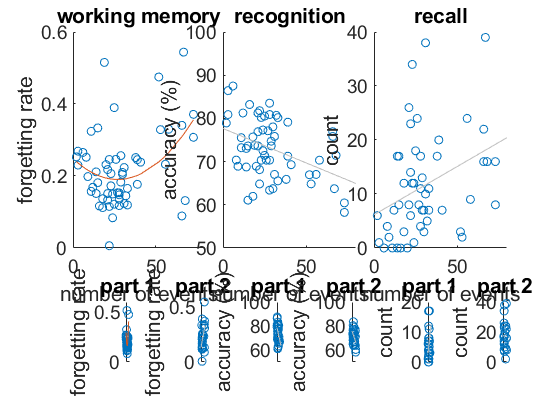

figure;
D = sortrows(D,'v17_total_events');
% segmentation and WM forgetting rate
subplot(3,6,[1 2 7 8]);
x = D.v17_total_events;
y = D.phi_WM;
scatter(x,y);xlim([0 80])
xlabel('number of events'); ylabel('forgetting rate'); title('working memory')
set(gca,'fontsize', 14)
hold on
p = polyfit(x,y,2); 
f = polyval(p,x); 
plot(x,f) 

subplot(3,6, 13);
x = D.v17_total_events(D.group == 'lab');
y = D.phi_WM(D.group == 'lab');
scatter(x,y);xlim([0 80]); ylim([0 0.6])
xlabel('number of events'); ylabel('forgetting rate'); title('part 1')
set(gca,'fontsize', 14)
hold on
p = polyfit(x,y,2); 
f = polyval(p,x); 
plot(x,f) 

subplot(3,6,14);
x = D.v17_total_events(D.group == 'online');
y = D.phi_WM(D.group == 'online');
scatter(x,y);xlim([0 80]);lsline
xlabel('number of events'); ylabel('forgetting rate'); title('part 2')
set(gca,'fontsize', 14)

% segmentation and recognition
subplot(3,6,[3 4 9 10 ]);
x = D.v17_total_events;
y = D.allRecognitionAcc*100;
scatter(x,y);xlim([0 80]);lsline; ylim([50 100])
xlabel('number of events'); ylabel('accuracy (%)'); title('recognition')
set(gca,'fontsize', 14)

subplot(3,6, 15);
x = D.v17_total_events(D.group == 'lab');
y = D.allRecognitionAcc(D.group == 'lab')*100;
scatter(x,y);xlim([0 80]);lsline;ylim([50 100])
xlabel('number of events'); ylabel('accuracy (%)'); title('part 1')
set(gca,'fontsize', 14)

subplot(3,6, 16);
x = D.v17_total_events(D.group == 'online');
y = D.allRecognitionAcc(D.group == 'online')*100;
scatter(x,y);xlim([0 80]);lsline;ylim([50 100])
xlabel('number of events'); ylabel('accuracy (%)'); title('part 2')
set(gca,'fontsize', 14)

% segmentation and realis
subplot(3,6,[5 6 11 12]);
x = D.v17_total_events(~isnan(D.nWords));
y = D.nRealis(~isnan(D.nWords));
scatter(x,y);xlim([0 80]);lsline
xlabel('number of events'); ylabel('count'); title('recall')
set(gca,'fontsize', 14)

subplot(3,6, 17);
x = D.v17_total_events(~isnan(D.nWords) & D.group == 'lab');
y = D.nRealis(~isnan(D.nWords) & D.group == 'lab');
scatter(x,y);xlim([0 80]);lsline
xlabel('number of events'); ylabel('count'); title('part 1')
set(gca,'fontsize', 14)

subplot(3,6, 18);
x = D.v17_total_events(~isnan(D.nWords) & D.group == 'online');
y = D.nRealis(~isnan(D.nWords) & D.group == 'online');
scatter(x,y);xlim([0 80]);lsline
xlabel('number of events'); ylabel('count'); title('part 2')
set(gca,'fontsize', 14)